cd /Users/serg/github_projects/QASS_SVM/data
load iris.mat
gam = 0.44

gam = 0.4400

sig2 = 0.21

sig2 = 0.2100

% Train the classification model.
[ alpha , b ] = trainlssvm ({ Xtrain , Ytrain , 'c', gam , sig2 ,'RBF_kernel'}) ;
% Classification of the test data.
[ Yest , Ylatent ] = simlssvm ({ Xtrain , Ytrain , 'c', gam , sig2 ,'RBF_kernel'} , { alpha , b } , Xtest ) ;
% Generating the ROC curve.
figure;
roc( Ylatent , Ytest ) 

ans = 1

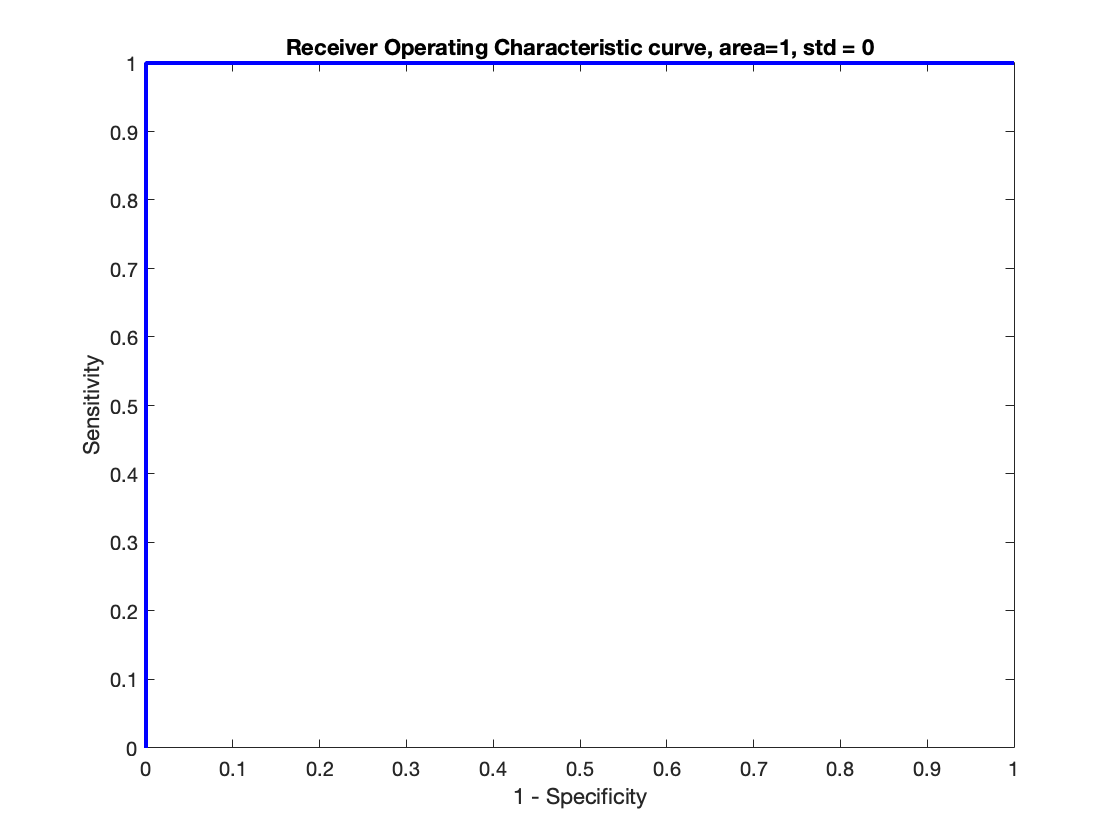

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_134.png','Resolution',300)